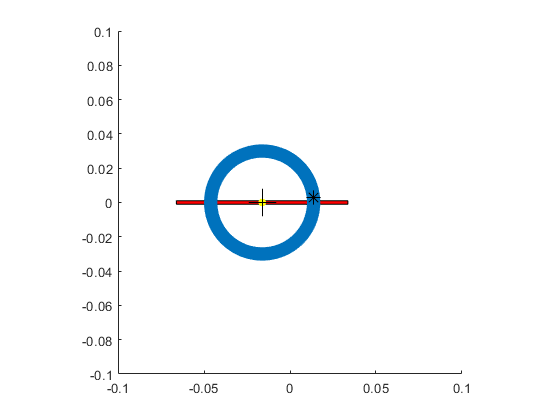

mass = 0.1; %kg
radius = 0.03; %m

oc_mass = 0.001; %kg
oc_pos = [0.03 ; 0]; %m

com = oc_mass * oc_pos;

com_offset = norm(com);
oc_offset = norm(oc_pos);

I = (0.5 * mass * radius^2) + (oc_mass * norm(oc_pos)^2);

angular_velocity = 1000 * 2*pi / 60;
angular_acceleration = 0;


beam_mass = 40; %kg
beam_width = 0.1; %m
beam_pos = 0;
beam_vel = 0;
beam_acc = 0;



dt = 0.001;
t_range = 0:dt:0.12;
torque = 0;
theta = 0;

animate = true;

data = [];



for t = t_range

    torque = com_offset * 9.8 * (oc_mass + mass) * sin(theta);
    angular_acceleration = torque / I;
    angular_velocity = angular_velocity + dt * angular_acceleration;
    theta = theta + (dt * angular_velocity);
    linear_force = (angular_velocity^2 * com_offset) / com_offset * cos(theta);
    
    
    
    
    beam_acc = linear_force / beam_mass;
    beam_vel = beam_vel + beam_acc * dt;
    beam_pos = beam_pos + beam_vel * dt;  
    
    
    
    com = [com_offset * cos(theta) ; com_offset * sin(theta)];
    
    oc_pos = [oc_offset * cos(theta) ; oc_offset * sin(theta)];
    
    
    
    data(end+1,:) = [t  com(1)  com(2)  theta  angular_velocity  angular_acceleration  linear_force beam_pos];
    
    
    
    if animate
    
    
        figure(4)
        clf
        
        axis equal
        
        axis([-0.1 0.1 -0.1 0.1])
        
        hold on
        
        beam = rectangle("Position", [beam_pos - (beam_width / 2), -0.001, beam_width, 0.002], "FaceColor", 'r');
        
        tc = linspace(0,2*pi,1000);
        x = radius*cos(tc);
        y = radius*sin(tc);
        
        plot(beam_pos + x, y, "LineWidth", 10)
        plot(beam_pos +  com(1), com(2), ".", "Markersize", 20, "Color", "y")
        plot(beam_pos + 0, 0, "+", "Markersize", 20, "Color", 'k')
        plot(beam_pos +  oc_pos(1), oc_pos(2), "*", "Markersize", 10, "Color", 'k')
        hold off
        drawnow
        
    end


end

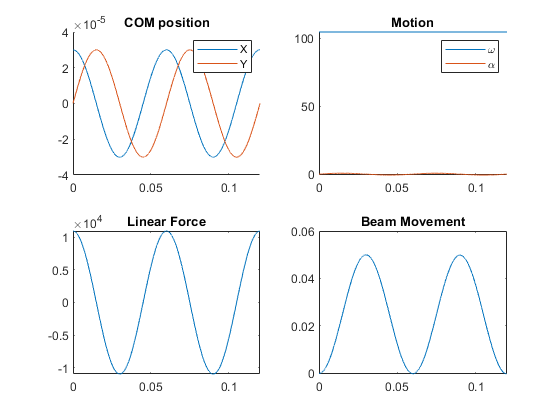

figure()
clf
subplot(2,2,1)
hold on
plot(data(:,1), data(:,2))
plot(data(:,1), data(:,3))
legend("X", "Y")
hold off
title("COM position")

subplot(2,2,2)
hold on
plot(data(:,1), data(:,5))
plot(data(:,1), data(:,6))
legend('\omega', '\alpha')
hold off
title("Motion")

subplot(2,2,3)
plot(data(:,1), data(:,7))
title("Linear Force")

subplot(2,2,4)
plot(data(:,1), data(:,8))
title("Beam Movement")

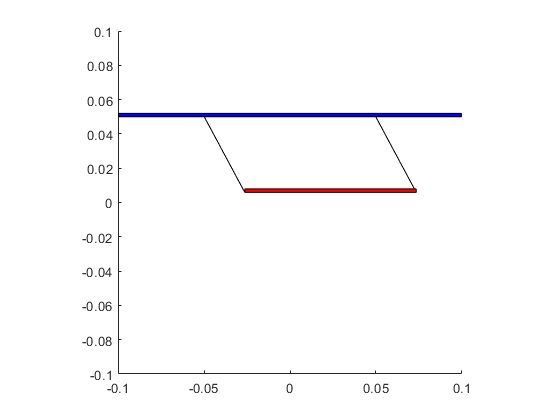




beam_mass = 40; %kg
beam_width = 0.1; %m
beam_thick = 0.002; %m

beam_vel = 0;
beam_acc = 0;
theta = pi/6;
alpha = 0;
omega = 0;
plot_data = [];
animate = true;

beam_pos = [0 ; 0];

m_rod = 0.1;
l_rod = 0.05;

dt = 0.01;
I = 1/3 * m_rod * l_rod^2;

for t=0:dt:5
   
    linear_force = 0.2*sin(2*pi*20*t);
    %linear_force = 0;
    tau_in = linear_force * l_rod * sin(pi/2-theta);
    tau_grav = 2* (l_rod / 2) * m_rod * -9.8 * sin(theta);
    tau_net = tau_in + tau_grav;
    alpha = tau_net / I;
    omega = omega + alpha * dt;
    theta = theta + omega * dt;
    plot_data(end+1,:) = [t tau_in tau_grav tau_net theta];
    

    
    if animate
        figure(4)
        clf
        
        axis equal
        
        axis([-0.1 0.1 -0.1 0.1])
        
        hold on
        
        
        mount =  rectangle("Position", [beam_pos(1) - (beam_width), 0.05, beam_width* 2, beam_thick], "FaceColor", 'b');
        rod1x = [-0.05 -0.05 + l_rod * sin(theta)];
        rod1y = [0.05 0.05 - l_rod * cos(theta)];
        rod2x = [0.05 0.05 + l_rod*sin(theta)];
        rod2y = [0.05 0.05 - l_rod*cos(theta)];

        
        
        
        plot(rod1x, rod1y, 'Color', 'k')
        plot(rod2x, rod2y, 'Color', 'k')
        
        
        beam = rectangle("Position", [rod1x(2), rod1y(2), beam_width, beam_thick], "FaceColor", 'r');

        hold off
        drawnow
    end
end

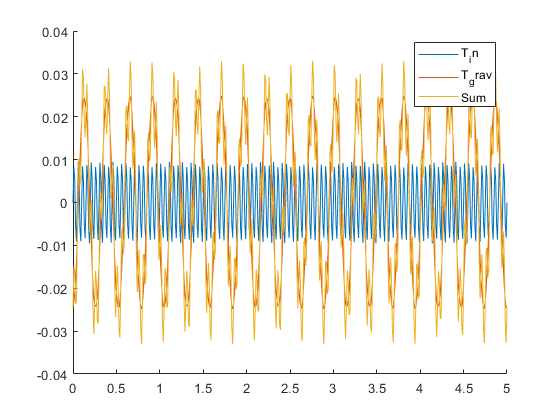

figure()
clf
hold on
plot(plot_data(:,1), plot_data(:,2))
plot(plot_data(:,1), plot_data(:,3))
plot(plot_data(:,1), plot_data(:,4))
legend("T_in", "T_grav", "Sum")

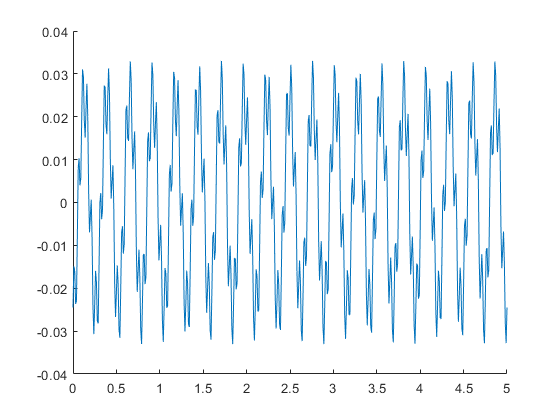


figure()
clf
hold on
plot(plot_data(:,1), plot_data(:,4))

sum = plot_data(:,4) - cos(17.1484 * plot_data(:,1));
%plot(plot_data(:,1), sum)



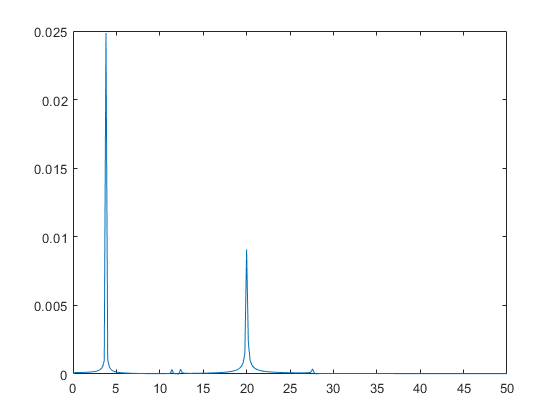

figure()
clf
Y = fft(plot_data(:,4));
Fs = 1/dt;
T = 1/Fs;
L = length(plot_data(:,1))-1;

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f, P1)


%t = linspace(0,pi,50)';

% Fs = 1000;            % Sampling frequency                    
% T = 1/Fs;             % Sampling period       
% L = 1500;             % Length of signal
% t = (0:L-1)*T;        % Time vector
% 
% S = 0.7*sin(2*pi*50*t) + sin(2*pi*120*t);
% X = S + 2*randn(size(t));
% Y = fft(X);P2 = abs(Y/L);
% P1 = P2(1:L/2+1);
% P1(2:end-1) = 2*P1(2:end-1);
% 
% f = Fs*(0:(L/2))/L;
% plot(f,P1) 
% title('Single-Sided Amplitude Spectrum of X(t)')
% xlabel('f (Hz)')
% ylabel('|P1(f)|')
